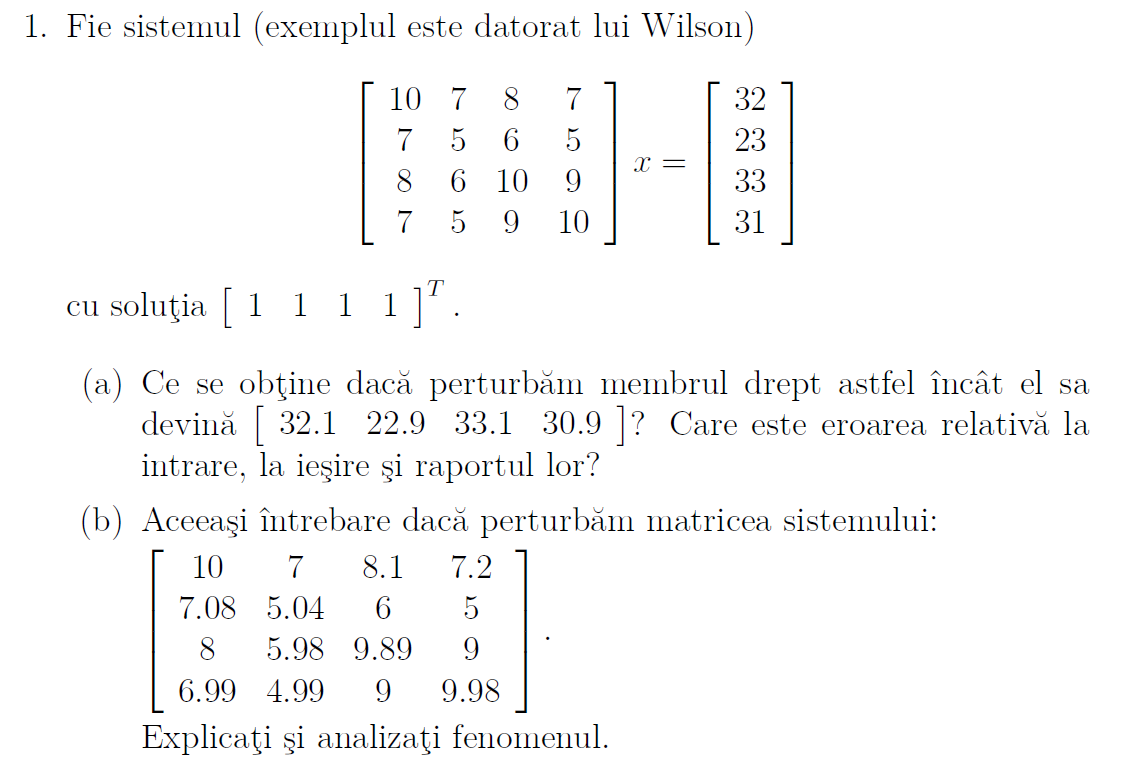

first = [10 7 8 7; 
        7 5 6 5;
        8 6 10 9;
        7 5 9 10];
third = [32;23;33;31];
third_perturbat = [32.1; 22.9; 33.1; 30.9];
second = first \ third

second =     1.0000
    1.0000
    1.0000
    1.0000


second_perturbat = first \ third_perturbat

second_perturbat =     9.2000
  -12.6000
    4.5000
   -1.1000



eroare_in = third - third_perturbat;
eroare_relativa_in = norm(eroare_in) / norm(third)

eroare_relativa_in = 0.0033


eroare_out = second - second_perturbat;
eroare_relativa_out = norm(eroare_out) / norm(second)

eroare_relativa_out = 8.1985


raport = vpa(eroare_relativa_out / eroare_relativa_in)

$$raport = 2460.5672364314214064506813883781$$

clear all;
first = [10 7 8 7; 
        7 5 6 5;
        8 6 10 9;
        7 5 9 10];
first_perturbat = [10 7 8.1 7.2;
                    7.08 5.04 6 5;
                    8 5.98 9.89 9;
                    6.99 4.99 9 9.98;];
third = [32;23;33;31];
second = first \ third

second =     1.0000
    1.0000
    1.0000
    1.0000


second_perturbat = first_perturbat \ third

second_perturbat =   -81.0000
  137.0000
  -34.0000
   22.0000



eroare_in = first - first_perturbat;
eroare_relativa_in = norm(eroare_in) / norm(first);

eroare_out = second - second_perturbat

eroare_out =    82.0000
 -136.0000
   35.0000
  -21.0000


eroare_relativa_out = norm(eroare_out) / norm(second)

eroare_relativa_out = 81.9848

raport = vpa(eroare_relativa_out / eroare_relativa_in)

$$raport = 10757.882994722373041440732777119$$